Remove Excess Figures

clc
clear
close all

Variable Initialization

global n
global L
P = 400/6;

n = 1000; % Number of locations to evaluate bridge failure
L = 1250; % Length of bridge
x = linspace(0, L, n); % Define x coordinate
SFD_PL = zeros(1, n); % Initialize SFD(x)


Sectional Properties

% There are many (more elegant ways) to construct cross-section objects
xc = [20 790 L]; % Location, x, of cross-section change
bft = [100 100 100]; % Top Flange Width
tft = [1.27 1.27 1.27] * 2; % Top Flange Thickness
hw = [88.73 88.73 88.73]; % Web Height
tw = [1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs)
dw = [68.73 68.73 68.73];
bfb = [70 70 100]; % Bottom Flange Width
tfb = [2.54 1.27 2.54]; % Bottom Flange Thickness
a = [20 263 262 30 160 160 160 30 80 80 30 25]; % Diaphragm Spacing
%ac = [0 10 535 565 725 885 1045 1075 1155 1235 1265 1290]; %Diaphragm Locations from support A (note u must have one at start of bridge) so n + 1
% [0 10 535 565 740 770 1045 1075 1175 1205 1270 1290]  double up supports
% and point loads
ac = [10 273 535 565 725 885 1045 1075 1175 1205 1270 1290]

ac =           10         273         535         565         725         885        1045        1075        1175        1205        1270        1290


h = tft + tfb + hw; %total height
ttg = [10 10 10]; %thickness of glue tab


Material Properties

SigT = 30;
SigC = 6;
E = 4000;
TauU = 4;
TauG = 2;
mu = 0.2;



Point Load Analysis

Train at right end

wheel_point = [394, 570, 734, 910, 1074, 1250]; % train in middle of the bridge
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(1), (400/6), x, SFD_PL);
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(2), (400/6), x, SFD_PL);
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(3), (400/6), x, SFD_PL);
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(4), (400/6), x, SFD_PL);
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(5), (400/6), x, SFD_PL);
    [SFD_PL, BMD_PL] = ApplyPL(wheel_point(6), (400/6), x, SFD_PL);
    %wheel_point = wheel_point + i;

Call Functions

[ ybar, I, Q, Q_glue] = SectionProperties( xc, bft, tft, hw, tw, bfb, tfb);
% plot(x, ybar, 'b--')
% title('ybar')
% 
% plot(x, I, 'r--')
% title('I')
% 
% plot(x, Q, 'y--')
% title('Q') 
V_Mat = Vfail( ybar, I, Q, xc, tfb, bfb, hw, bft, tw, TauU, 0, ttg);
V_Glue = Vfail( ybar, I, Q_glue, xc, tfb, bfb, hw, bft, tw, TauG, 1, ttg);
V_Buck = VfailBuck(a, tw, hw, I, Q, E, mu, xc, ac);
M_MatT = MfailMatT(I, ybar, h, SigT, BMD_PL, xc);
M_MatC = MfailMatC(I, ybar, h, SigC, BMD_PL, xc);
M_Buck1 = MfailBuck(tw, tft, bft, tfb, bfb, hw, E, I, mu, BMD_PL, 1, xc, ybar, dw);
M_Buck2 = MfailBuck(tw, tft, bft, tfb, bfb, hw, E, I, mu, BMD_PL, 2, xc, ybar, dw);
M_Buck3 = MfailBuck(tw, tft, bft, tfb, bfb, hw, E, I, mu, BMD_PL, 3, xc, ybar, dw);
Pf = FailLoad( P, SFD_PL, BMD_PL, V_Mat, V_Glue, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3 )

ans =     4.9250   25.4290    5.3686    9.8442    3.6810   11.4858   23.5824   19.1257


ans = 3.6810

Pf = 245.4030

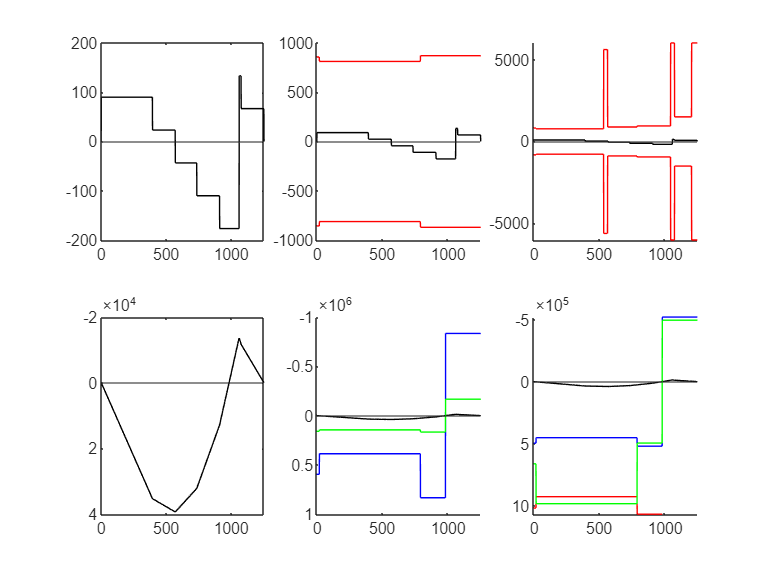

VisualizePL(x, SFD_PL, BMD_PL, V_Mat, V_Buck, M_MatT, M_MatC, M_Buck1, M_Buck2, M_Buck3, Pf)

% deflection = deflection(x, BMD_PL, I, E)


